# Simscape multibody model of Regbot in balance

initial setup with motor velocity controller this is intended as simulation base for balance control.

close all
clear

## Simulink model name

model='regbot_1mg';

## parameters for REGBOT

motor

RA = 3.3/2;    % ohm (2 motors)
JA = 1.3e-6*2; % motor inertia
LA = 6.6e-3/2; % rotor inductor (2 motors)
BA = 3e-6*2;   % rotor friction
Kemf = 0.0105; % motor constant
Km = Kemf;
% køretøj
NG = 9.69; % gear
WR = 0.03; % wheel radius
Bw = 0.155; % wheel distance
% 
% model parts used in Simulink
mmotor = 0.193;   % total mass of motor and gear [kg]
mframe = 0.32;    % total mass of frame and base print [kg]
mtopextra = 0.97 - mframe - mmotor; % extra mass on top (charger and battery) [kg]
mpdist =  0.10;   % distance to lit [m]
% disturbance position (Z)
pushDist = 0.1; % relative to motor axle [m]

## wheel velocity controller (no balance) PI-regulator

sample (usable) controller values

Kpwv = 15;     % Kp
tiwv = 0.05;   % Tau_i
Kffwv = 0;     % feed forward constant
startAngle = 10;  % tilt in degrees at time zero
twvlp = 0.005;    % velocity noise low pass filter time constant (recommended)

## Motor voltage to wheel velocity

### Estimate transfer function for base system using LINEARIZE

Motor volatge to wheel velocity (wv)

load_system(model);
open_system(model);
% define points in model
ios(1) = linio(strcat(model,'/Limit9v'),1,'openinput');
ios(2) = linio(strcat(model, '/wheel_vel_filter'),1,'openoutput');
% attach to model
setlinio(model,ios);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,ios,op);
% get transfer function
[num,den] = ss2tf(sys.A, sys.B, sys.C, sys.D);
Gwv = minreal(tf(num, den))

Gwv =
 
                                                 
  7.023e05 s^3 + 7.023e08 s^2 - 5.083e07 s       
                                                 
                                       - 5.083e10
                                                 
  -----------------------------------------------
                                                 
  s^6 + 2418 s^5 + 1.317e06 s^4 + 1.872e08 s^3   
                                                 
           + 2.371e09 s^2 - 3.032e10 s - 1.881e11
                                                 
 
Continuous-time transfer function.



### Bodeplot

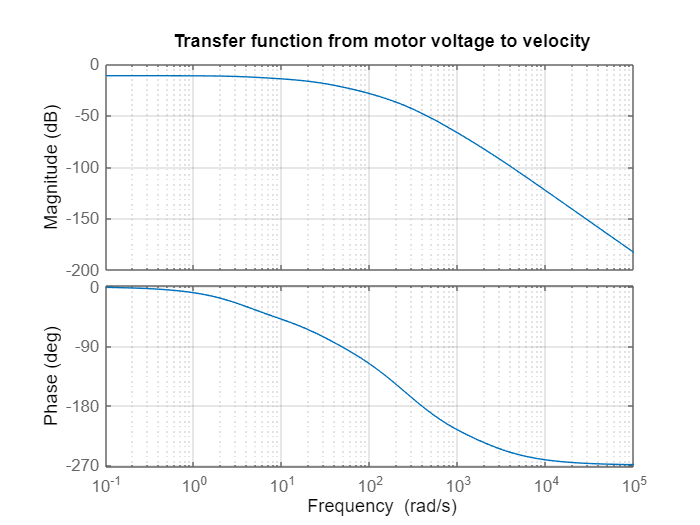

h = figure(100);
bode(Gwv)
grid on
title('Transfer function from motor voltage to velocity')
saveas(h, 'motor to velocity.png');

## Voltage to tilt angle

### Estimate transfer function for base system using LINEARIZE

Motor volatge to angle (va)

load_system(model);
open_system(model);
% define points in model
iosang(1) = linio(strcat(model,'/Step'),1,'openinput');
iosang(2) = linio(strcat(model, '/robot with balance'),1,'openoutput');
% attach to model
setlinio(model,iosang);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,iosang,op);
% get transfer function
[numang,denang] = ss2tf(sys.A, sys.B, sys.C, sys.D);
Gva = minreal(tf(numang, denang))

Gva =
 
                                                 
  -5.893e05 s^4 - 7.71e08 s^3 - 1.435e11 s^2     
                                                 
                          - 2.566e12 s - 7.683e09
                                                 
  -----------------------------------------------
                                                 
  s^7 + 2418 s^6 + 1.317e06 s^5 + 1.977e08 s^4   
                                                 
          + 1.312e10 s^3 + 1.796e11 s^2          
                                                 
                          - 9.658e11 s - 1.525e13
                                                 
 
Continuous-time transfer function.



### Bodeplot

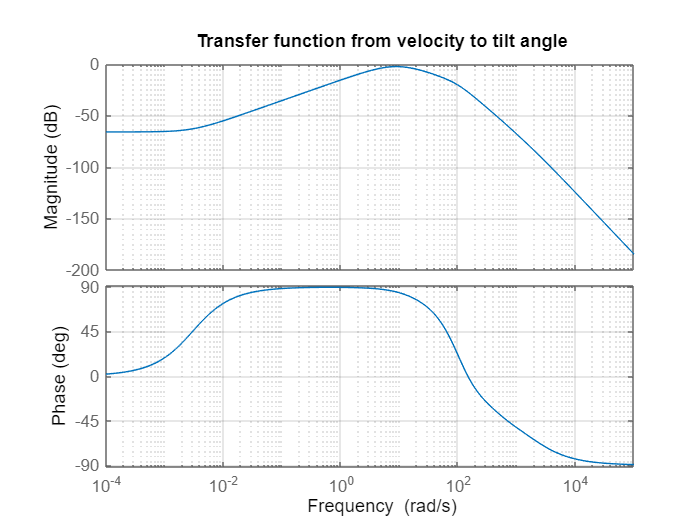

figure(101);
bode(Gva)
grid on
title('Transfer function from velocity to tilt angle')  

### Stabilize the system

Get the bode of the transfer function multiplied by -1

Find the peak in the bode plot

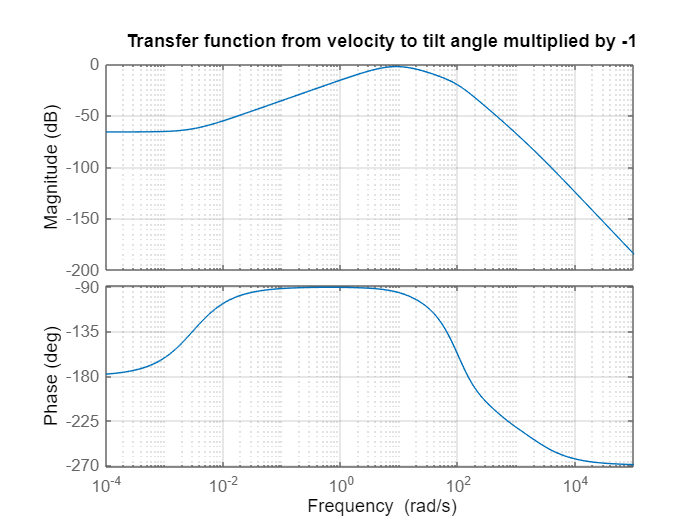

figure();
bode(-1*Gva)
grid on
title('Transfer function from velocity to tilt angle multiplied by -1')

#### Design the PI controller to stabilize the system

Implement a PI controller right where there is a peak in the bode plot

s = tf('s'); 
%Select the w_i in rad/s -> The PI will be placed at the peak at 10 rad/s
w_i = 10

w_i = 10

tau_i = 1/w_i;

% PI controller time constant and transfer function
C_PI = (1 + 1/(tau_i*s));

% Open-loop transfer function
%Remember we carry the -1 we firstly implemented
G_ol = minreal(-C_PI*Gva)

G_ol =
 
                                                 
  5.893e05 s^5 + 7.769e08 s^4 + 1.512e11 s^3     
                                                 
               + 4e12 s^2 + 2.567e13 s + 7.683e10
                                                 
  -----------------------------------------------
                                                 
  s^8 + 2418 s^7 + 1.317e06 s^6 + 1.977e08 s^5   
                                                 
          + 1.312e10 s^4 + 1.796e11 s^3          
                                                 
                      - 9.658e11 s^2 - 1.525e13 s
                                                 
 
Continuous-time transfer function.




%We define a w_c -> We want a good bandwidth
w_c = 2000;                 %How big should it be??

% P-controller gain
K_P = 1/abs(freqresp(G_ol,w_c*1i));

C_PI

C_PI =
 
  0.1 s + 1
  ---------
    0.1 s
 
Continuous-time transfer function.



K_P

K_P = 1.6156e+04

G_ol

G_ol =
 
                                                 
  5.893e05 s^5 + 7.769e08 s^4 + 1.512e11 s^3     
                                                 
               + 4e12 s^2 + 2.567e13 s + 7.683e10
                                                 
  -----------------------------------------------
                                                 
  s^8 + 2418 s^7 + 1.317e06 s^6 + 1.977e08 s^5   
                                                 
          + 1.312e10 s^4 + 1.796e11 s^3          
                                                 
                      - 9.658e11 s^2 - 1.525e13 s
                                                 
 
Continuous-time transfer function.



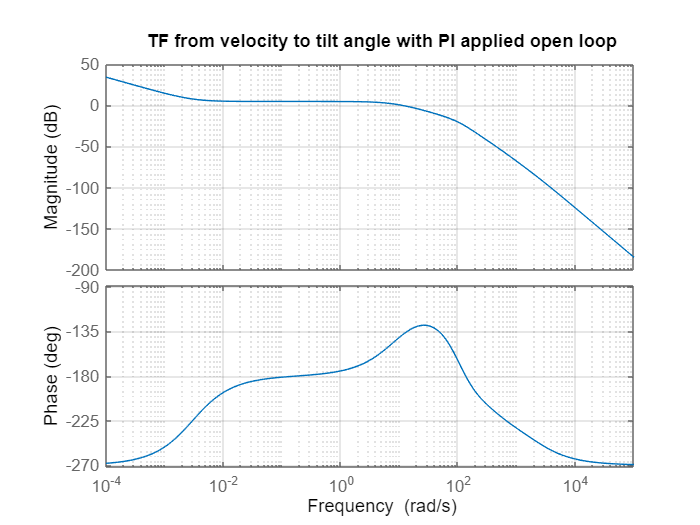

%poles(G_ol,s)

G_cl = minreal(K_P*G_ol/(1 + K_P*G_ol));

figure();
bode(G_ol)
grid on
title('TF from velocity to tilt angle with PI applied open loop')

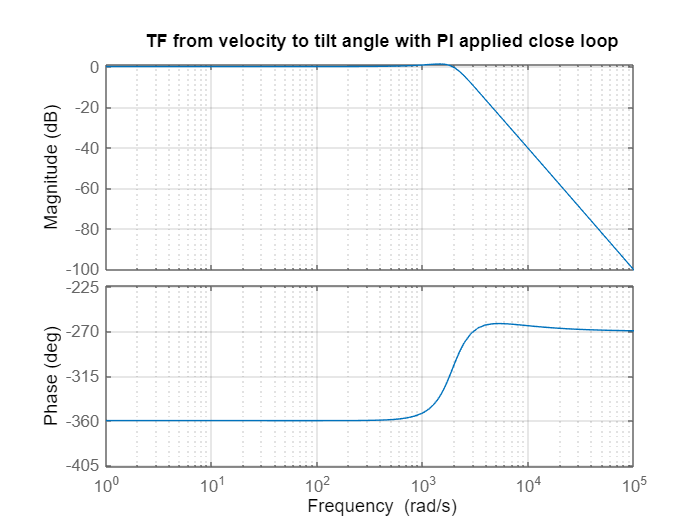


figure();
bode(G_cl)
grid on
title('TF from velocity to tilt angle with PI applied close loop')



stable_G = G_ol 

stable_G =
 
                                                 
  5.893e05 s^5 + 7.769e08 s^4 + 1.512e11 s^3     
                                                 
               + 4e12 s^2 + 2.567e13 s + 7.683e10
                                                 
  -----------------------------------------------
                                                 
  s^8 + 2418 s^7 + 1.317e06 s^6 + 1.977e08 s^5   
                                                 
          + 1.312e10 s^4 + 1.796e11 s^3          
                                                 
                      - 9.658e11 s^2 - 1.525e13 s
                                                 
 
Continuous-time transfer function.




isstable(G_cl)

ans = logical
   0


#### Nyquist plot of our new "stable" transfer function

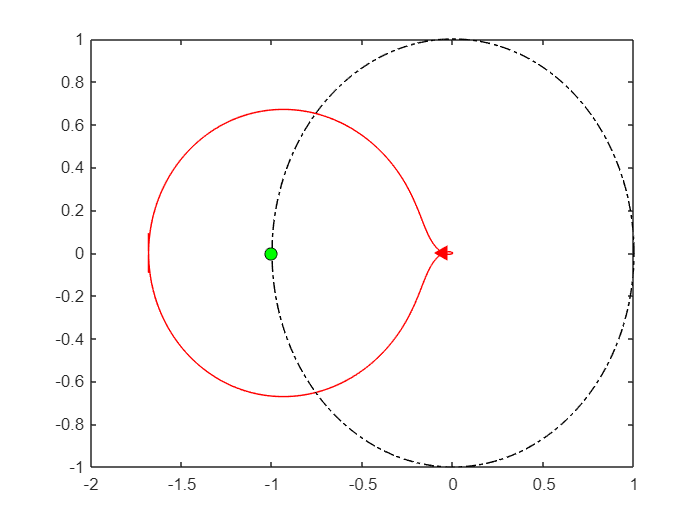

% Nyquist plots for the new tf G_ol
[re_G,im_G,w] = nyquist(G_ol,[-1e4:0.05:1e4]);
re_G = squeeze(re_G);
im_G = squeeze(im_G);
GG_unit = 1*exp(1i*(0:0.001:2*pi));

% Nyquist plots
figure;
plot(re_G,im_G,'r');
hold on;
plot(real(GG_unit),imag(GG_unit),'-.k');
scatter(-1,0,54,'markerFaceColor','g','MarkerEdgeColor','k');
i = find(angle(re_G + 1i*im_G) >= pi/3,1);
scatter(re_G(i),im_G(i),54,'<',...
    'markerFaceColor','r','MarkerEdgeColor','r');
hold off;

## Doing the real controllers

### Tilt controller 

The G_ol is gonna be the new transfer function

figure;
G = stable_G

G =
 
                                                 
  5.893e05 s^5 + 7.769e08 s^4 + 1.512e11 s^3     
                                                 
               + 4e12 s^2 + 2.567e13 s + 7.683e10
                                                 
  -----------------------------------------------
                                                 
  s^8 + 2418 s^7 + 1.317e06 s^6 + 1.977e08 s^5   
                                                 
          + 1.312e10 s^4 + 1.796e11 s^3          
                                                 
                      - 9.658e11 s^2 - 1.525e13 s
                                                 
 
Continuous-time transfer function.



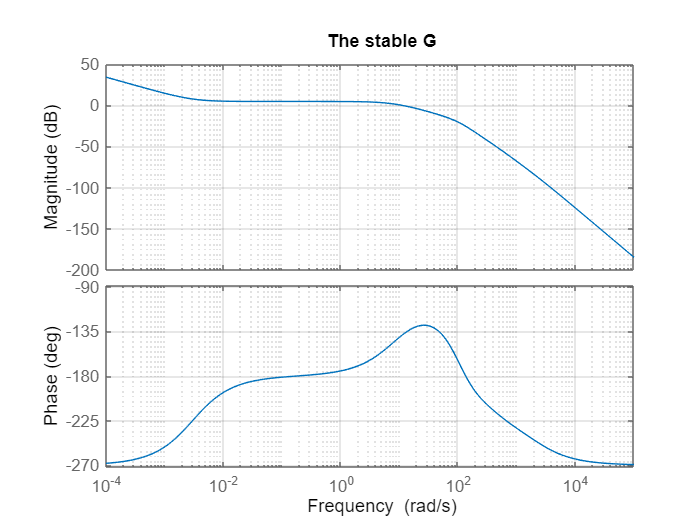

bode(stable_G)
grid on
title('The stable G')

isstable(stable_G)

ans = logical
   0


[`B`](https://se.mathworks.com/help/control/ref/lti.isstable.html#mw_8d73cc9b-94bd-42ef-a81a-43b420085d2e) `= isstable(`[`sys`](https://se.mathworks.com/help/control/ref/lti.isstable.html#mw_3008ce15-0a87-48d3-b205-3aea109099e9)`)` returns a logical value of `1` (`true`) if the [dynamic system model](https://se.mathworks.com/help/control/ug/dynamic-system-models.html) `sys` has stable dynamics, and a logical value of `0` (`false`) otherwise. If `sys` is a model array, then the function returns `1` only if all the models in `sys` are stable.

G = stable_G

G =
 
                                                 
  5.893e05 s^5 + 7.769e08 s^4 + 1.512e11 s^3     
                                                 
               + 4e12 s^2 + 2.567e13 s + 7.683e10
                                                 
  -----------------------------------------------
                                                 
  s^8 + 2418 s^7 + 1.317e06 s^6 + 1.977e08 s^5   
                                                 
          + 1.312e10 s^4 + 1.796e11 s^3          
                                                 
                      - 9.658e11 s^2 - 1.525e13 s
                                                 
 
Continuous-time transfer function.



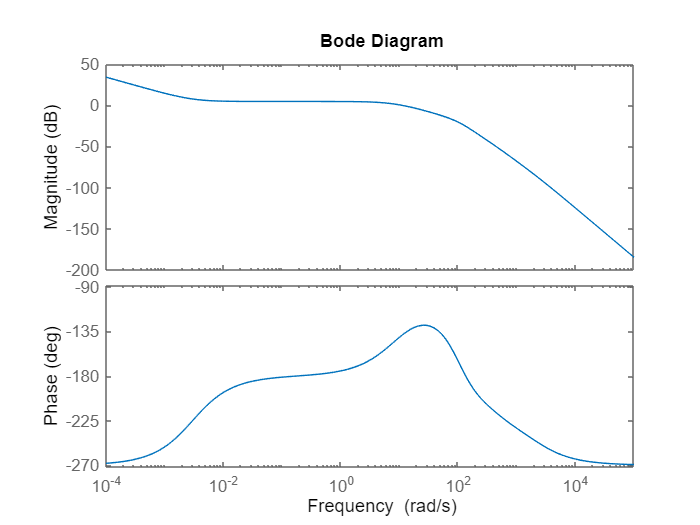

s = tf('s');                        % Define complex variable
%bode(G)
%hold on
[MAG,PHASE,W] = bode(G);
MAG = mag2db(squeeze(MAG));
PHASE = squeeze(PHASE);
bode(G);


%Define parameters
phase_margin = 60;
N_i = 3;
alpha = 0.2;

% Calculate the phase of the N_i and alpha (its already in degrees)
phi_i=-atand(1/N_i);    
phi_m= asind((1-alpha)/(1+alpha));

%calculate new phase of G(s)
phase_G = phase_margin - phi_i - phi_m - 180

phase_G = -143.3754


%Find w_c from the bode plot of G(s) as the frequency at which <G(jwc) = phase_G
id = find(PHASE <= phase_G,1);
w_c = W(id)

w_c = 1.0000e-04

deg2rad(w_c)

ans = 1.7453e-06


% PI controller time constant and transfer function
tau_i = N_i/w_c;
C_PI = (1 + 1/(tau_i*s));

% P-Lead controller time constant and transfer function
tau_d = 1/(w_c*sqrt(alpha));
C_D = (tau_d*s + 1)/(alpha*tau_d*s + 1);

% Open-loop transfer function
G_ol = minreal(C_PI*C_D*G);

% P-controller gain
K_P = 1/abs(freqresp(G_ol,w_c));

C_PI

C_PI =
 
  30000 s + 1
  -----------
    30000 s
 
Continuous-time transfer function.



C_D

C_D =
 
  2.236e04 s + 1
  --------------
    4472 s + 1
 
Continuous-time transfer function.



K_P

K_P = 0.0084

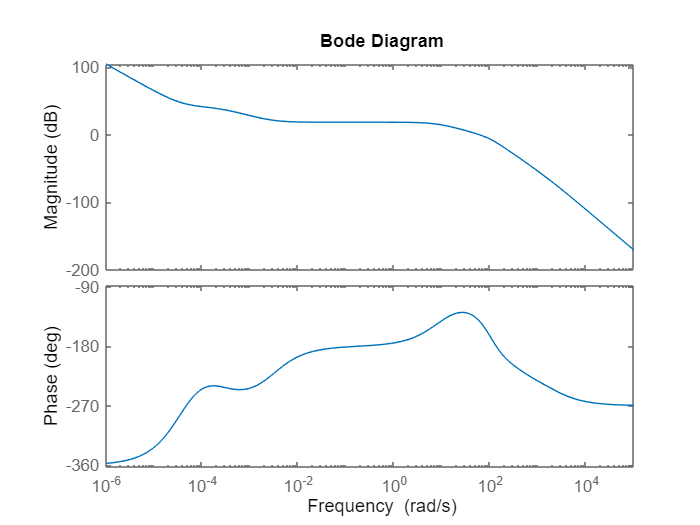


bode(G_ol)

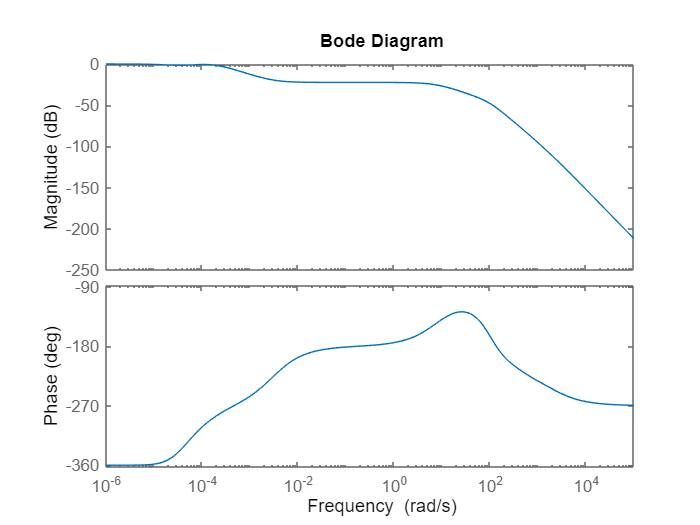

G_cl = minreal(K_P*G_ol/(1 + K_P*G_ol));
figure;
bode(G_cl)